# Robotics 2 - Final Exam  - July 11, 2018

## Exercise 1

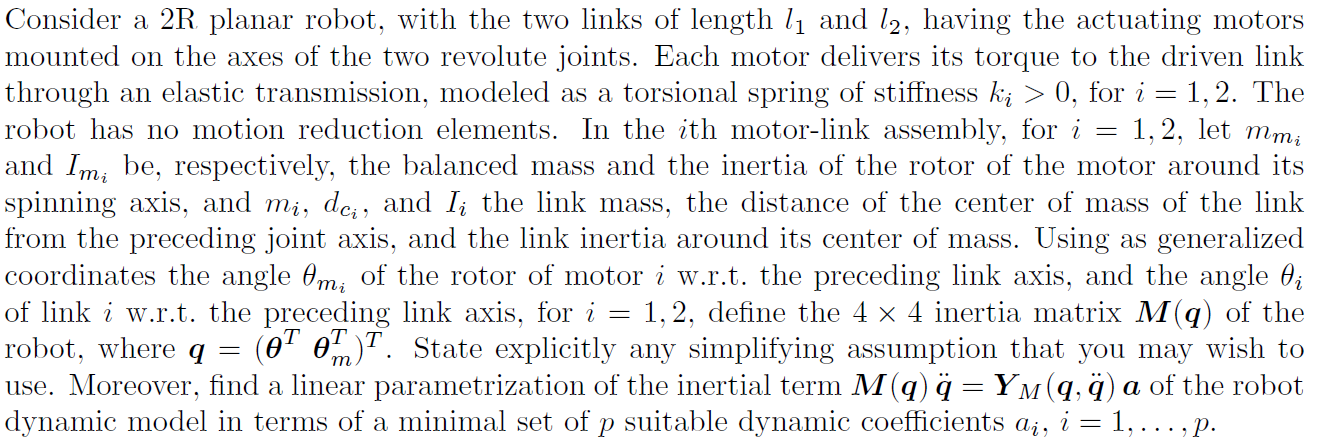

## my aproach

% clear;clc
% % 
% % % syms k q1(t) q2(t) q3(t)
% sigma = [0,0];
% n = length(sigma);
% % t = sym('t', 'real');
% % q = sym('q_', [n 1],'real');
% % q_dot = sym('q_dot_', [n 1],'real');
% % q_ddot = sym('q_ddot_', [n 1],'real');
% 
% q = sym('theta_', [n 1],'real');
% q_dot = sym('theta_dot_', [n 1],'real');
% q_ddot = sym('theta_ddot_', [n 1],'real');
% 
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% 
% % motor definitions
% % q_m = sym('q_m_', [n 1],'real');
% % q_dot_m = sym('q_dot_m_', [n 1],'real');
% % q_ddot_m = sym('q_ddot_m_', [n 1],'real');
% 
% q_m = sym('theta_m_', [n 1],'real');
% q_dot_m = sym('theta_dot_m_', [n 1],'real');
% q_ddot_m = sym('theta_ddot_m_', [n 1],'real');
% 
% 
% %
% % dc = sym('dc_', [n 1],'real');
% 
% % l = sym('l_', [n 1],'real');
% m_m = sym('m_m_', [n 1],'real');
% I_m = sym('I_m_', [n 1],'real');
% 
% 
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[g0,0,0]';

defining z struct

% R2Robot=['rr';'xx';sigma]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.m=m;
% z.I=I;
% 
% z.q_m=q_m;
% z.q_dot_m=q_dot_m;
% z.q_ddot_m=q_ddot_m;
% z.m_m=m_m;
% z.I_m=I_m;
% 
% 
% z.dc=dc;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym('l','real')
% % z.opt_expr={l,[l_0,l_0,l_0,l_0]'};%not necessary
% 
% % z.rcdefined=true;
% 
% z.ismotor=true;
% z.motoronly=false;
% z.vartoderivate="theta";

## axis offset

% % 
% % h=sym('h','real')
% % %x,y,z
% % z.xyx_offset=sym(zeros(3,n));
% % z.xyx_offset(:,1)=[0,h,0]'%

% % %Global q reference?
% % % clear
% % % z.q_global
% % z.global_q_reference=true
% % if(z.global_q_reference)
% %     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD)
% % end

% % 
% % %
% % %
% % % xyonly=true
% % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(R2Robot,l,q,qd,dc,m,I,xyonly)
% % % VarShortRobot.M
% % % angle_desired=[0,0]
% % % l(1)=0
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% % M
% % Pc
% % simplify((Ti'))
% % vc
% % simplify(Trans.PTotal)
% % Trans.PPartial{:}
% M_total=Trans.M_total

## getting dynamics parameters

% [Msubs, dynamicParamsReturn, a] = getDynamicParameters(M_total,[q;z.q_m],[])

## linear parametrization

% YM = getLinearParametrization(Msubs*[q_ddot;z.q_ddot_m], a)

## arci approach


% clear ;clc;
% sigma = [0,0]; % 0: Revolute, 1:Prismatic
% n = length(sigma);
% 
% % Link parameters
% q = sym('q', [1,n]).' ;
% qd = sym('qd', [1,n]).' ;
% l = sym('l', [1,n]).' ;
% m = sym('m', [1,n]).' ;
% d = sym('d', [1,n]).' ;
% I = sym('I', [1,n]).' ;
% qdd = sym('qdd',[1,n]).'
% 
% % Motor parameters
% qm = sym('qm', [1,n]).' ;
% qdm = sym('qdm', [1,n]).' ;
% lm = sym('lm', [1,n]).' ;
% mm = sym('mm', [1,n]).' ;
% dm = sym('dm', [1,n]).' ;
% Im = sym('Im', [1,n]).' ;
% qddm = sym('qddm',[1,n]).'
% 

% dm = sym('dm', [1,n])
% 
% [dhTable, Msubs, dynParams, a]  = getRR_Robot()

% % Just replace to distinguish l from I (Inertia)
% %dhTable = subs(dhTable,  sym('l', [1,n]).', L)

% % dhTable

### Computation of Kinetic Energy

% [KE_Links , Tlinks] = getKEwithJacobian(dhTable,sigma,q,qd,l,m,I,d,0)
% [KE_Motors , Tmotors] = getKEwithJacobian(dhTable,sigma,q,qd,l,m,I,d,1,qdm)

### Computation of Inertia matrix

% KE_Total = KE_Links + KE_Motors
% M = getInertiaMatrixFromKE(KE_Total,[qd;qdm])

% [Msubs, dynamicParamsReturn, a] = getDynamicParameters(M,[q;qm],[])

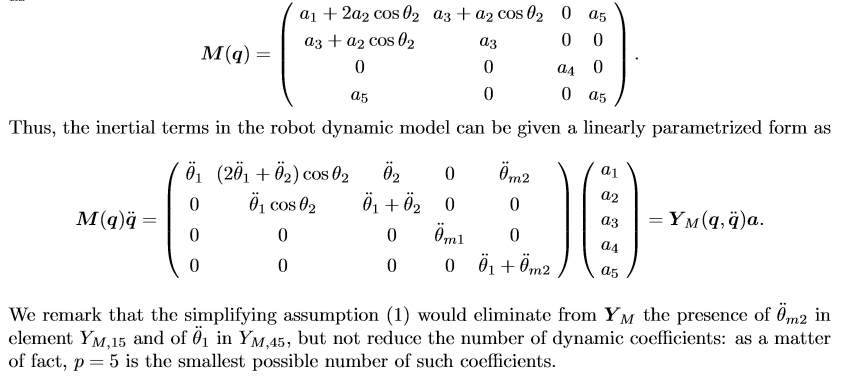

###  Computation of Linear Parametrization

% YM = getLinearParametrization(Msubs, [qdd;qddm], a)

## Exercise 2

**This is incomplete!!! The SNS algoruth has to be corrected and completed.**

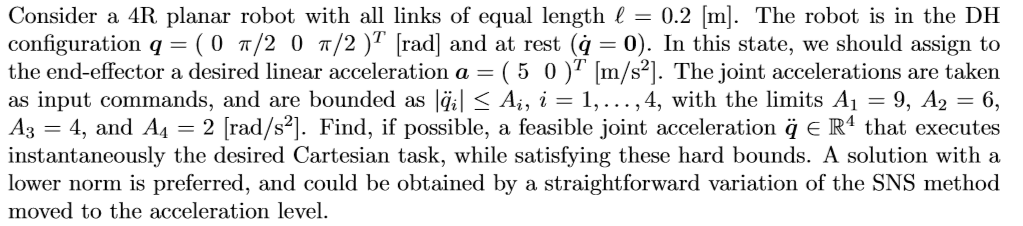

## my approach

% This part is isolated from previous section
clear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [0,0,0,0];
n = length(sigma);
% t = sym('t', 'real');
q = sym('q', [n 1],'real');
qd = sym('qd', [n 1],'real');
qdd = sym('qdd', [n 1],'real'); 
% 
dc = sym('dc', [n 1],'real');
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,0,-g0]';


R2Robot=['rrrr';'xxxx';sigma]  ;     
z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=qd;
z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1;
% z.dhTable=[]
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
z.xyonly=true;


[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×4 char]
                       l: [4×1 sym]
                      l_: []
                       q: [4×1 sym]
                   q_dot: [4×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [4×1 sym]
                       m: [4×1 sym]
                       I: [4×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 4
                  angle_: [1×4 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 1 1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
          

si falla aquí está el error
method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\mathrm{qd}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\mathrm{qd}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\mathrm{qd}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}\right)}^{2}}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \begin{array}{l} \left(\begin{array}{ccc} \frac{{{\mathrm{qd}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\mathrm{qd}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}\right)}^{2}}{2} & \frac{m_{3}\,\left({{\mathrm{qd}}_{2}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+\sigma_{1}+{l_{2}}^{2}\right)+{{\mathrm{qd}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{1}+\sigma_{1}+{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}\right)+{{\mathrm{dc}}_{3}}^{2}\,{{\mathrm{qd}}_{3}}^{2}+{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+4\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2}+2\,l_{1}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+2\,{l_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,l_{2}\right)+2\,{\mathrm{dc}}_{3}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}\,\left({\mathrm{dc}}_{3}+l_{2}\,\cos\left(q_{3}\right)\right)+2\,{\mathrm{dc}}_{3}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{3}\,\left({\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{3}\right)\right)\right)}{2}+\frac{I_{3}\,{\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}\right)}^{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

moving frames OFF!!


$$To\_derive = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1}-l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)-\sigma_{3} & -\sigma_{1}-l_{2}\,\sin\left(q_{1}+q_{2}\right)-\sigma_{3} & -\sigma_{1}-\sigma_{3} & -\sigma_{1}\\ \sigma_{2}+l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+\sigma_{4} & \sigma_{2}+l_{2}\,\cos\left(q_{1}+q_{2}\right)+\sigma_{4} & \sigma_{2}+\sigma_{4} & \sigma_{2}\\ 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=l_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{3}=l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right)\\ q_{4}\left(t\right) \end{array}\right)$$

    "check the _ last term it is needed for the function for example q_1_ should be the right way to define a varaible to convert to time dependent"



z_derivated = struct with fields:
    dot_t: [3×4 sym]


z_derivated = struct with fields:
     dot_t: [3×4 sym]
    ddot_t: [3×4 sym]


z_derivated = struct with fields:
     dot_t: [3×4 sym]
    ddot_t: [3×4 sym]
    tdot_t: [3×4 sym]


z_derivated = struct with fields:
        dot_t: [3×4 sym]
       ddot_t: [3×4 sym]
       tdot_t: [3×4 sym]
          dot: [3×4 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×4 sym]
       ddot_t: [3×4 sym]
       tdot_t: [3×4 sym]
          dot: [3×4 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []
          tdot: [3×4 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []
          tdot: [3×4 sym]
    tdot_short: []


$$To\_derive = \left(\begin{array}{c} l_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ l_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right)\\ q_{4}\left(t\right) \end{array}\right)$$

    "check the _ last term it is needed for the function for example q_1_ should be the right way to define a varaible to convert to time dependent"



z_derivated = struct with fields:
    dot_t: [2×1 sym]


z_derivated = struct with fields:
     dot_t: [2×1 sym]
    ddot_t: [2×1 sym]


z_derivated = struct with fields:
     dot_t: [2×1 sym]
    ddot_t: [2×1 sym]
    tdot_t: [2×1 sym]


z_derivated = struct with fields:
        dot_t: [2×1 sym]
       ddot_t: [2×1 sym]
       tdot_t: [2×1 sym]
          dot: [2×1 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [2×1 sym]
       ddot_t: [2×1 sym]
       tdot_t: [2×1 sym]
          dot: [2×1 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [2×1 sym]
        ddot_t: [2×1 sym]
        tdot_t: [2×1 sym]
           dot: [2×1 sym]
     dot_short: []
          ddot: [2×1 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [2×1 sym]
        ddot_t: [2×1 sym]
        tdot_t: [2×1 sym]
           dot: [2×1 sym]
     dot_short: []
          ddot: [2×1 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [2×1 sym]
        ddot_t: [2×1 sym]
        tdot_t: [2×1 sym]
           dot: [2×1 sym]
     dot_short: []
          ddot: [2×1 sym]
    ddot_short: []
          tdot: [2×1 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [2×1 sym]
        ddot_t: [2×1 sym]
        tdot_t: [2×1 sym]
           dot: [2×1 sym]
     dot_short: []
          ddot: [2×1 sym]
    ddot_short: []
          tdot: [2×1 sym]
    tdot_short: []


$$To\_derive = \begin{array}{l} \left(\begin{array}{cccc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & \sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sigma_{4} & {\mathrm{dc}}_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+\sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\sigma_{4}\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) & \sigma_{1}+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sigma_{3} & {\mathrm{dc}}_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+\sigma_{1}+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sigma_{3}\\ 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{3}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right)\\ q_{4}\left(t\right) \end{array}\right)$$

    "check the _ last term it is needed for the function for example q_1_ should be the right way to define a varaible to convert to time dependent"



z_derivated = struct with fields:
    dot_t: [3×4 sym]


z_derivated = struct with fields:
     dot_t: [3×4 sym]
    ddot_t: [3×4 sym]


z_derivated = struct with fields:
     dot_t: [3×4 sym]
    ddot_t: [3×4 sym]
    tdot_t: [3×4 sym]


z_derivated = struct with fields:
        dot_t: [3×4 sym]
       ddot_t: [3×4 sym]
       tdot_t: [3×4 sym]
          dot: [3×4 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×4 sym]
       ddot_t: [3×4 sym]
       tdot_t: [3×4 sym]
          dot: [3×4 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []
          tdot: [3×4 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []
          tdot: [3×4 sym]
    tdot_short: []


$$f = \left(\begin{array}{c} l_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ l_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

$$J = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1}-l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)-\sigma_{3} & -\sigma_{1}-l_{2}\,\sin\left(q_{1}+q_{2}\right)-\sigma_{3} & -\sigma_{1}-\sigma_{3} & -\sigma_{1}\\ \sigma_{2}+l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+\sigma_{4} & \sigma_{2}+l_{2}\,\cos\left(q_{1}+q_{2}\right)+\sigma_{4} & \sigma_{2}+\sigma_{4} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2}=l_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{3}=l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$V = \left(\begin{array}{c} -l_{1}\,{\mathrm{qd}}_{1}\,\sin\left(q_{1}\right)-l_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\,\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}+{\mathrm{qd}}_{4}\right)-l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\,\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}\right)-l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}\right)\\ l_{1}\,{\mathrm{qd}}_{1}\,\cos\left(q_{1}\right)+l_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\,\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}+{\mathrm{qd}}_{4}\right)+l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\,\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}\right)+l_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{qd}}_{1}+{\mathrm{qd}}_{2}\right) \end{array}\right)$$

PCVar = struct with fields:
         PTotali: [2×4 sym]
              Pc: [3×4 sym]
              vc: [3×4 sym]
     f_derivated: [1×1 struct]
           f_dot: [2×1 sym]
          f_ddot: [2×1 sym]
          f_tdot: [2×1 sym]
    pc_derivated: [1×1 struct]
         Pc_ddot: [3×4 sym]
               w: [3×4 sym]
               T: [1×1 sym]
              Ti: [1×4 sym]
               M: [4×4 sym]


PC_EEShort = struct with fields:
          f: [2×1 sym]
          J: [2×4 sym]
          V: [2×1 sym]
         Pc: [3×4 sym]
    Pc_ddot: []
    PTotali: [3×4 sym]


VarShortRobot = struct with fields:
    Pc: [3×4 sym]
    vc: [3×4 sym]
     w: [3×4 sym]
     T: [1×1 sym]
    Ti: [1×4 sym]
     M: [4×4 sym]


% VarShortRobot.M
% angle_desired=[0,alpha_angle]
% [Pc,vc,w,T,Ti,M] = getGenericPC(R2Robot,l,q,qd,dc,m,I,1,[],[],'alpha',false,angle_desired)
% [C,cac,Csubs,S] = getCs(M,q,qd)
% 
% % [C,cac,Csubs] = getCs(Msubs,q',qd')
% u =simplify( M*qdd + cac)

vars2replace=[l;q]

$$vars2replace = \left(\begin{array}{c} l_{1}\\ l_{2}\\ l_{3}\\ l_{4}\\ q_{1}\\ q_{2}\\ q_{3}\\ q_{4} \end{array}\right)$$

l0_=0.2;
q_=[0,pi/2,0,pi/2]'; 
l_=[l0_,l0_,l0_,l0_]';

vars2replace_=[l_;q_]

vars2replace_ =     0.2000
    0.2000
    0.2000
    0.2000
         0
    1.5708
         0
    1.5708



J_=subs(J,vars2replace,vars2replace_)

$$J\_ = \left(\begin{array}{cccc} -\frac{2}{5} & -\frac{2}{5} & -\frac{1}{5} & 0\\ 0 & -\frac{1}{5} & -\frac{1}{5} & -\frac{1}{5} \end{array}\right)$$

## sns


V_=[5,0]'

V_ =      5
     0


q_dMax_ = [9,6,4,2] % Maximum acceleration constraints of joints

q_dMax_ =      9     6     4     2


% 
q_dMaxTemp_ = q_dMax_ % Maximum acceleration constraints of joints

q_dMaxTemp_ =      9     6     4     2



vpa(J_)

$$ans = \left(\begin{array}{cccc} -0.4 & -0.4 & -0.2 & 0\\ 0 & -0.2 & -0.2 & -0.2 \end{array}\right)$$

rank_J_=rank(J_)

rank_J_ = 2

rank_V_=rank(V_)

rank_V_ = 1

if(rank_J_<2)
disp("Range of J_ is lower than 2  IT IS NOT FULL RANK PAY ATTENTION!!")
if(rank_J_==rank_V_)
disp("but The rank is inside of rank V_ all are: "+rank_J_)
disp("BUT CHECK IF V_ INSIDE OF THE RANGE OF R{j}, SEE THE FORM WHEN IT IS OR NOT CERO!!")
end
end

abs_on=true;
autodetectsign=true

autodetectsign = logical
   1


[qdotstarFinal] = SNSMethod1(V_,J_,q_dMax_',abs_on,autodetectsign)

qdotPS =    -8.3333
   -4.1667
         0
    4.1667


qdotstar =    -8.3333
   -4.1667
         0
    4.1667


negativeslocales = 4×1 logical array
   1
   1
   0
   0


converting q_dot as negative PAY ATTENTION!!!!! abs=false also


abs_on = logical
   0


q_dMax_ =     -9
    -6
    -4
    -2


Max value that violates is:  4  with value:  2.1667
SNS Iterarion:  1


$$ans = \left(\begin{array}{c} 5.0\\ -0.4 \end{array}\right)$$

Jtemp #:  4


$$Jtemp = \left(\begin{array}{ccc} -\frac{2}{5} & -\frac{2}{5} & -\frac{1}{5}\\ 0 & -\frac{1}{5} & -\frac{1}{5} \end{array}\right)$$

Jtemp pseudo inverse #:  4


$$psJ\_ = \left(\begin{array}{cc} -2.2222222222222222222222222222222 & 3.3333333333333333333333333333333\\ -0.55555555555555555555555555555556 & -1.6666666666666666666666666666667\\ 0.55555555555555555555555555555556 & -3.3333333333333333333333333333333 \end{array}\right)$$

qdot_components =   -12.4444   -2.1111    4.1111


qdot_sns =   -12.4444
   -2.1111
    4.1111


Max value that violates is:  1  with value:  3.4444
SNS Iterarion:  1


$$ans = \left(\begin{array}{c} 1.4\\ -0.4 \end{array}\right)$$

Jtemp #:  1


$$Jtemp = \left(\begin{array}{cc} -\frac{2}{5} & -\frac{1}{5}\\ -\frac{1}{5} & -\frac{1}{5} \end{array}\right)$$

Jtemp pseudo inverse #:  1


$$psJ\_ = \left(\begin{array}{cc} -5.0 & 5.0\\ 5.0 & -10.0 \end{array}\right)$$

qdot_components =     -9    11


qdot_sns =     -9
    11


Max value that violates is:  3  with value:  7
SNS Iterarion:  1


$$ans = \left(\begin{array}{c} 0.6\\ -1.2 \end{array}\right)$$

Jtemp #:  3


$$Jtemp = \left(\begin{array}{c} -\frac{2}{5}\\ -\frac{1}{5} \end{array}\right)$$

Jtemp pseudo inverse #:  3


$$psJ\_ = \left(\begin{array}{cc} -2.0 & -1.0 \end{array}\right)$$

qdot_components = 0

qdot_sns = 0

[INFO] No values are exceeding the limits.
Result:


qdotstarFinal =     -9
     0
    -4
    -2


qdotstarFinal =     -9
     0
    -4
    -2



[qdotstarFinal,W] = SNSMethod2(V_,J_,q_dMax_')%,Qdotmin,Qdotdmax)

Assuming qN positive if it is not in this way comment this line  PAY ATTENTION!


n = 4

Violatedvalue = logical
   1


SNS Iterarion:  1
The valued that violate are:  "4"  with values:  "35/6"
Actual Most Critical Join is:  4
Actual Scaling factor is:  2/25


$$qdotstar = \left(\begin{array}{c} -\frac{20}{3}\\ -\frac{35}{6}\\ 0\\ \frac{35}{6} \end{array}\right)$$

Violatedvalue = logical
   1


SNS Iterarion:  2
The valued that violate are:  "1"  with values:  "-83/9"
Actual Most Critical Join is:  1
Actual Scaling factor is:  49/50


$$qdotstar = \left(\begin{array}{c} -\frac{83}{9}\\ -\frac{41}{9}\\ \frac{23}{9}\\ 2 \end{array}\right)$$

Result:


$$qdotstar = \left(\begin{array}{c} -9\\ -5\\ 3\\ 2 \end{array}\right)$$

$$qdotstarFinal = \left(\begin{array}{c} -9\\ -5\\ 3\\ 2 \end{array}\right)$$

W =      0     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     0



vpa(qdotstarFinal)

$$ans = \left(\begin{array}{c} -9.0\\ -5.0\\ 3.0\\ 2.0 \end{array}\right)$$

pd2_=vpa(J_)*qdotstarFinal

$$pd2\_ = \left(\begin{array}{c} 5.0\\ 0 \end{array}\right)$$

vpa(norm(qdotstarFinal))

$$ans = 10.908712114635714411502154487373$$

## arci aproach


% disp('** Exercise 2')
% clear ;clc;
% sigma = [0,0,0,0]; % 0: Revolute, 1:Prismatic
% n = length(sigma);
% 
% % Link parameters
% q = sym('q', [1,n]).' ;
% qd = sym('qd', [1,n]).' ;
% l = sym('l') ;
% m = sym('m', [1,n]).' ;
% d = sym('d', [1,n]).' ;
% I = sym('I', [1,n]).' ;
% qdd = sym('qdd',[1,n]).'
% 
% dhTable = [0, l, 0, q(1);
%            0, l, 0, q(2);
%            0, l, 0, q(3);
%            0, l, 0, q(4)]
% 
% q0 = [0, pi/2, 0, pi/2].'; % initial configuration.
% qd0 = [0,0,0,0].'; % Initial velocity at rest.
% 

% % Calculate the Jacobian (Rotational)
% [Jp, Jo] = getJacobian(dhTable,sigma,'alpha')
% %Jac = [Jp;Jo]
% %Eliminate the zero rows, which represent the unused variables
% Jp = Jp(~all(Jp == 0,2),:)
% 
% J = subs(Jp, [q; l], [q0 ; 0.2])

% SNS_sol(J, xdd, A)

% % Acceleration limits
% A = [9,6,4,2];
% 
% % SNS (Saturation on Null Space)
% xdd= [5,0].'
% qddPS = eval(pinv(J))*xdd
% maxvalue = 1
% qddstar = qddPS
% qdd_sns = qddPS
% while maxvalue > 0
%     [maxvalue, maxindex] = max(abs(qddstar)-abs(A')) % The positive values are violating the limit. We take the highest one.
%     if (maxvalue > 0) % if there is an exceeding value
%         s = A(1)/qddstar(maxindex)    
%         %xdot_sns  = xdot - J(:,maxindex)* sign(qdotPS(maxindex))*V(maxindex)
%         %Same as 
%         xdot_sns  = xdd - abs(J(:,maxindex)*A(maxindex));
%         Jtemp = J
%         Jtemp(:,maxindex) = [];
%         qdot_components = eval(pinv(Jtemp)*xdot_sns).' 
%         qdd_sns = [qdot_components(1:maxindex-1), A(maxindex), qdot_components(maxindex:end)]
%         qddstar = qdd_sns;
%     else
%         disp("[INFO] No values are exceeding the limits.")
%         disp('Result:')
%         qddstar
%     end
% end

## Exercise 3